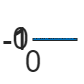

[X, Fs] = audioread("lab_09_signal.wav");
figure
plot(X)

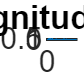

%n = 0:N-1
%w = K*(2*pi/N) for some K.
N = length(X);
%cos(K*(2*pi/N))

n = (0:N-1).' ;
k = n ;
figure
plot(k,abs(X)), title(['Magnitude of X'])

plot(k,angle(X)), title(['Phase of X'])
% fMAX = 754.817;
% BW= 2* 754.817;
K = N*754.817/Fs			% K = 24,759
sub = X-cos(K*(2*pi/N)*n);
plot(X-cos(K*(2*pi/N)*n))
soundsc(sub, Fs);
soundsc(X, Fs);